# Channel Estimation through deep learning : ChanNetEst

*ChanEstNet: A Deep Learning Based Channel Estimation for High-Speed Scenarios*,*Yong Liao, Yuanxiao Hua, Xuewu Dai†, Haimei Yao, Xinyi Yang*

The paper proposes the following neural network structure for channel estimation using pilots :

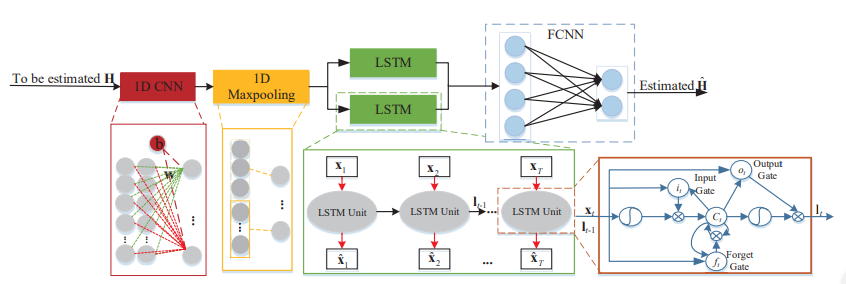

## Constructing the input data :

- We use SISO OFDM modulation for the input data with 4-QAM as the mapping technique.

- Cyclic prefix of length 16 is used to avoid ISI.

- Number of carriers is taken as $N_c$ = 64.

- We consider 20 symbols ($N_{s}$)  as one sub frame of the OFDM transmission. Each subframe has 4 pilots $N_p$ symbols evenly distributed.

nCarr = 64 ; % Number of carriers
cp_len = 16; % Length of cyclic prefix
nSym = 20;   % Number of symbols
n_tx = 1 ;   % Number of transmitting antennaes

[ofdm_mod,ofdm_demod] = OFDMConfig(nCarr,cp_len,nSym,n_tx); % Creating the OFDM de/modulaion objects

Undefined variable "comm" or class "comm.OFDMModulator".

Error in OFDMConfig (line 17)
ofdm_mod = comm.OFDMModulator; % Modulation Object

[waveform, data_pil] = OFDM_Tx(ofdm_mod); % Creating the OFDM waveform which will be transmitted 
                                          % across the channel and getting the QAM data and pilots.

## Channel Modelling :

The channel array is already provided in the form of a .mat file which contains 16 taps evolving across time. 

For each 16 element channel array we convolve it with the OFDM symbol to get the channel distorted array.

We add AWGN noise to the this distorted array to get the final received array to which we apply deomulation and detection.

channel_train = load ('chaneel_train.mat'); % Training labels for neural network
channel_test = load ('channel_train.mat');  % Testing data for NN

function [rx_sig] = channel_output(h,tx_sig,SNR)
% Gives the output after the transmitted OFDM waveform passes 
% through the channel.
    y= conv(h,tx_sig);
    sigPow = y*y'; 
    noise_mag = sqrt((10.^(-SNR/10))*sigPow/2);
    rx_sig = y + noise_mag*(randn(size(y))+1j*randn(size(y)));
end

## Preprocessing for the input data:

- The received OFDM signal is demdoulated and the pilots are extracted

- LS estimate is used to predict the $\hat{H}[k]$  values for those subcarriers where the pilots are present.

- The incomplete input $\hat{H}$matrix is fed into the neural network. The matrix is a $N_{c}$  x $N_{s}$. So wherever the pilots are present in the each of the symbols we have the $\hat{H_{LS}}[k]$ values and for the rest of the $N_{c} x (N_{s} - N_{p})
$ elements we consider them to be zeros, whose values will be determined by the neural network.